clear all

%Data given
%Grundfläche der Tanks
A_data=[15.52;90.52;15.52;15.52];
%Grundfläche ausgangslöcher
a_data=[0.1678;0.1542;0.06743;0.06504];
%WasserLevel im Arbeitspunkt.
h0=[18;18;14;19];
%pumpen und Sensor parameter
k=[4.32;3.74];
kh=0.2; 
g=981;
gamma=[0.625;0.625];
wc=0.2;

w = logspace(-4,4,100);
w2 = logspace(-4,0,100);


T=A_data./a_data.*sqrt(2.*h0./g);
%AdjazensMatrix
A=1./T.'.*eye(4)*(-1)+[0 0 A_data(3)/(A_data(1)*T(3)) 0;0 0 0 A_data(4)/(A_data(2)*T(4));0 0 0 0;0 0 0 0];
%B
B=[gamma(1)*k(1)/A_data(1) 0;0 gamma(2)*k(2)/A_data(2);0 (1-gamma(2))*k(2)/A_data(3);(1-gamma(1))*k(1)/A_data(4) 0];
%C
C=[kh 0 0 0;0 kh 0 0];
D=zeros(size(B,2),size(C,1));

sys=ss(A,B,C,D)


sys =
 
  A = 
              x1         x2         x3         x4
   x1   -0.05644          0    0.02572          0
   x2          0  -0.008892          0   0.003651
   x3          0          0   -0.02572          0
   x4          0          0          0   -0.02129
 
  B = 
            u1       u2
   x1    0.174        0
   x2        0  0.02582
   x3        0  0.09037
   x4   0.1044        0
 
  C = 
        x1   x2   x3   x4
   y1  0.2    0    0    0
   y2    0  0.2    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



G=tf(sys)


G =
 
  From input 1 to output...
         0.03479
   1:  -----------
       s + 0.05644
 
                7.621e-05
   2:  ---------------------------
       s^2 + 0.03019 s + 0.0001893
 
  From input 2 to output...
               0.0004648
   1:  --------------------------
       s^2 + 0.08216 s + 0.001451
 
         0.005165
   2:  ------------
       s + 0.008892
 
Continuous-time transfer function.



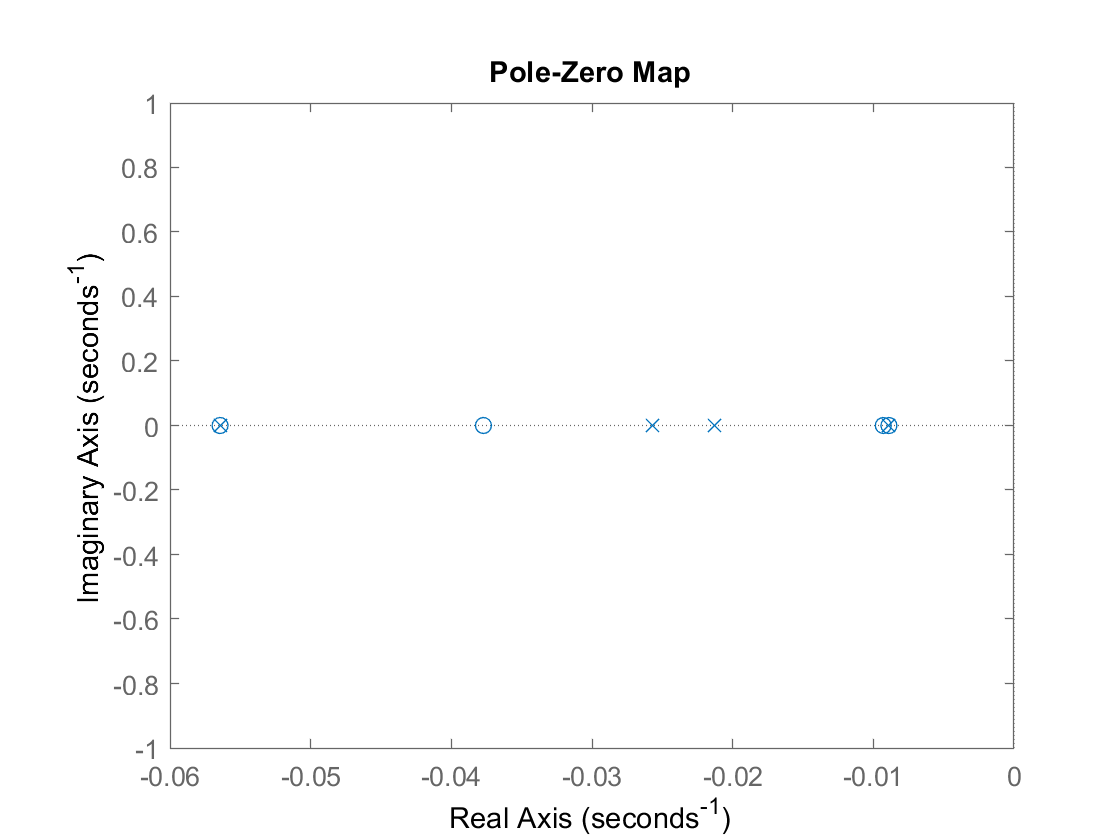

% Zeichne Pol und Nullstellen 
figure(1); pzmap(G);%hier kann man auch gut erkennen das es ein Minimalphasen system ist

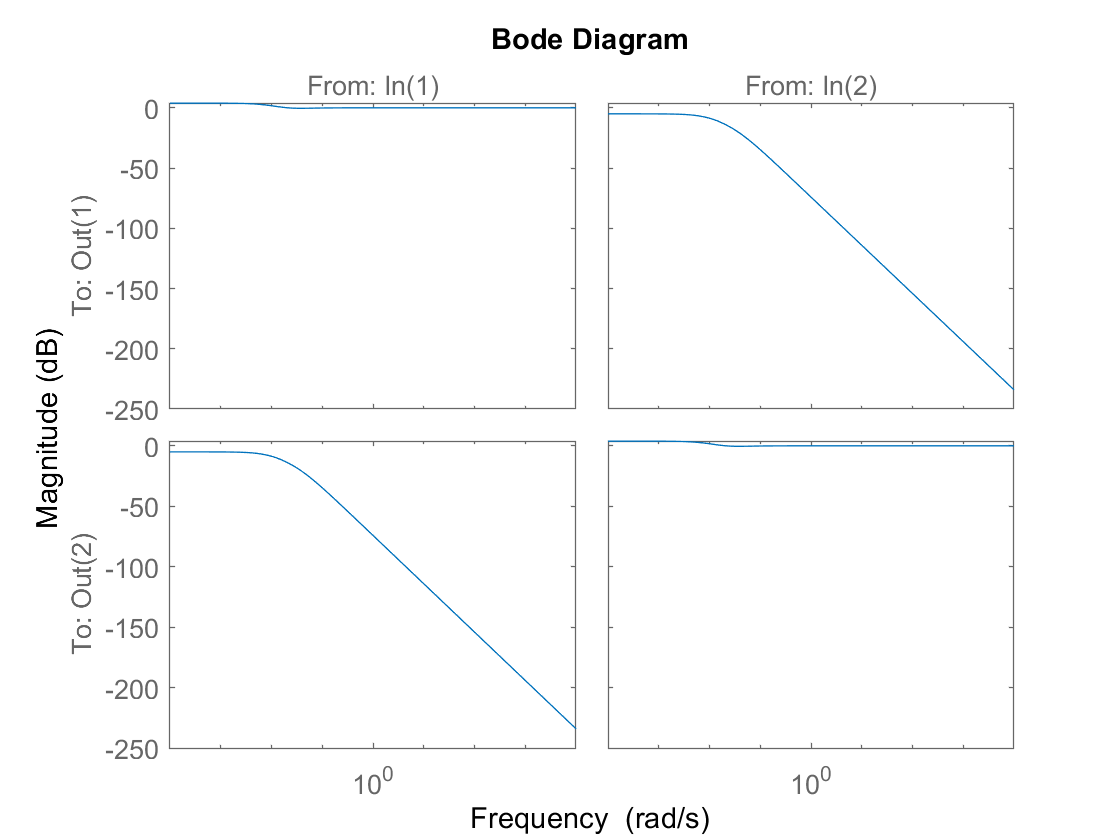

%%RGA ANALYSE
bodemag(RGA(G),w)

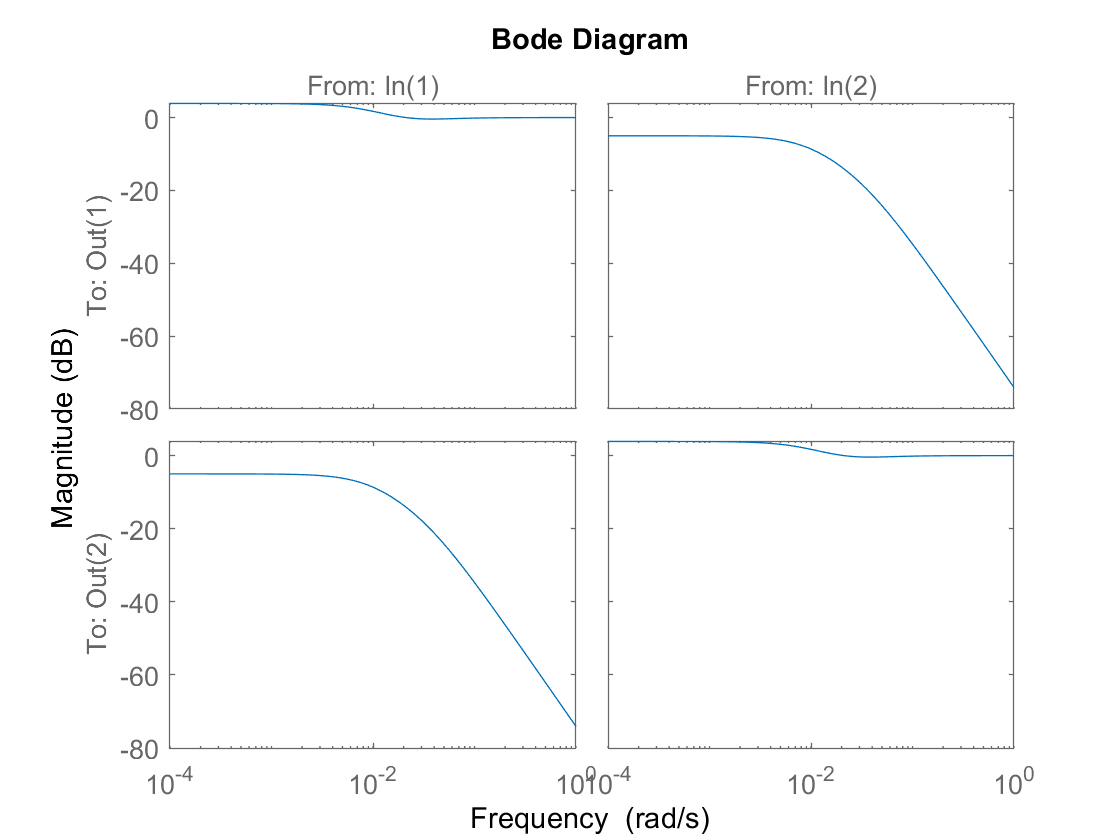

bodemag(RGA(G),w2)

RGA(evalfr(G,1i*100))

ans =    1.0000 - 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 - 0.0000i


%Aus den erhalten plos sieht man das umso höher die Frequenz um so näher an der Einheitsmatrix
%liegt G, daher kann man annehmen das die Querkoppling ein nicht so großen Einfluss aussübt. 
%Bzw
%Damit dezentrale Regelung Funktioniert -> sollte der Wert bei der Durchtrittsfrequenz 
%nahe bei Null Liegen. (also man will DiagonalDominaz veststellen)
Matrix_norm_sum(evalfr(G,i*wc)) %das ergebnis ist bei ~0 daher für Dezentrale Regelung geignet

ans = 0.0587 - 0.1823i

%%Dezentraller PI entwurf
%Grafischer Ansatz
%pidTuner(G(1,1));   %für grafische einstellung der Parameter
opts = pidtuneOptions('PhaseMargin',45,'CrossoverFrequency', 0.2);
[K11, info1] = pidtune(G(1,1),'PI',opts);
[K22, info2] = pidtune(G(2,2),'PI',opts);
display(info1);

info1 = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.2000
           PhaseMargin: 45


display(info2);

info2 = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.2000
           PhaseMargin: 45



K = [K11 0;0 K22]


K =
 
  From input 1 to output...
       2.918 s + 1.042
   1:  ---------------
              s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       26.17 s + 5.72
   2:  --------------
             s
 
Continuous-time transfer function.



G_ol = G*K


G_ol =
 
  From input 1 to output...
       0.1015 s + 0.03627
   1:  ------------------
        s^2 + 0.05644 s
 
           0.0002224 s + 7.944e-05
   2:  -------------------------------
       s^3 + 0.03019 s^2 + 0.0001893 s
 
  From input 2 to output...
            0.01216 s + 0.002659
   1:  ------------------------------
       s^3 + 0.08216 s^2 + 0.001451 s
 
       0.1351 s + 0.02954
   2:  ------------------
        s^2 + 0.008892 s
 
Continuous-time transfer function.



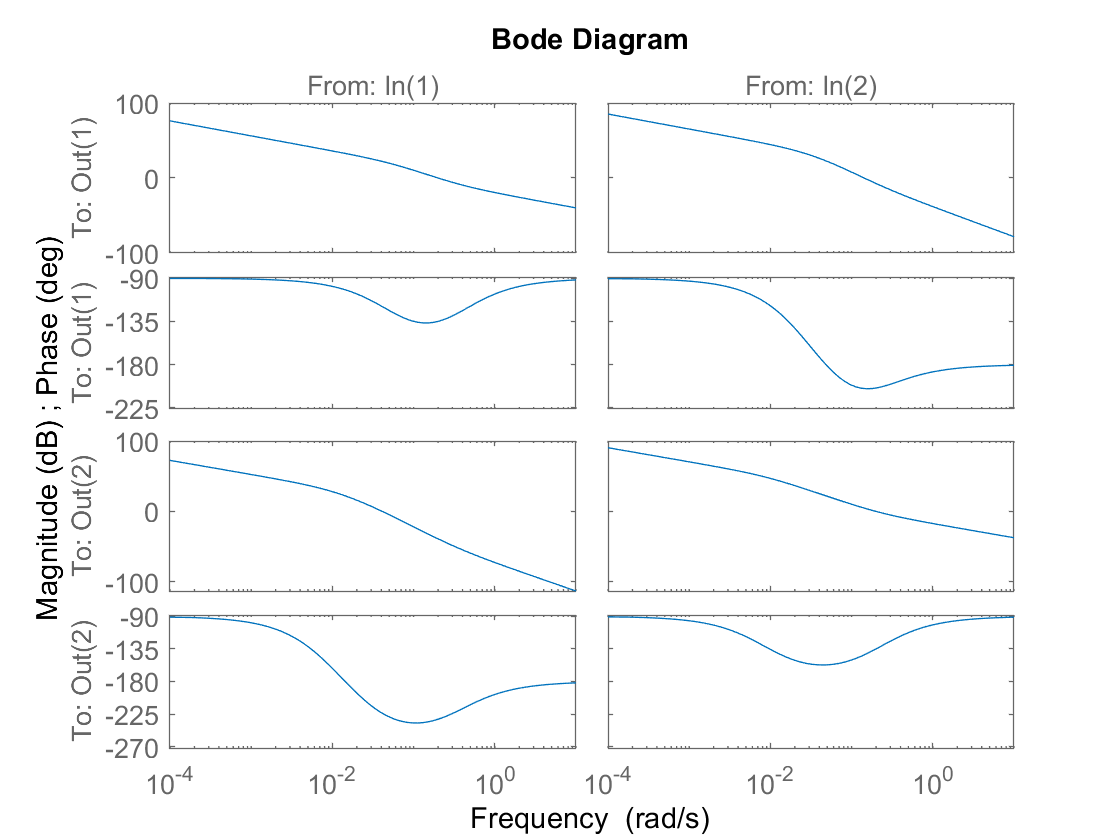

%feedback(G_ol,1)


% Bodediagramm der Strecke
figure(2); bodeplot(G_ol);

%%Stabilitätsüberprüfung
%E/A-Stabi
F=tf(eye(2))+G_ol


F =
 
  From input 1 to output...
       s^2 + 0.158 s + 0.03627
   1:  -----------------------
           s^2 + 0.05644 s
 
           0.0002224 s + 7.944e-05
   2:  -------------------------------
       s^3 + 0.03019 s^2 + 0.0001893 s
 
  From input 2 to output...
            0.01216 s + 0.002659
   1:  ------------------------------
       s^3 + 0.08216 s^2 + 0.001451 s
 
       s^2 + 0.144 s + 0.02954
   2:  -----------------------
          s^2 + 0.008892 s
 
Continuous-time transfer function.



Gw=G_ol/F;
Gw_det=G(1,1)*G(2,2)-G(1,2)*G(2,2);
F_det=F(1,1)*F(2,2)-F(1,2)*F(2,2);

diag_domi=0;
diag_domi=diag_domi+spaltendominant(F);
diag_domi=diag_domi+zeilendominant(F);
if(diag_domi >= 1)
    n_1=n_search(G_ol(1,1));
    n_11=(n_1(1,1)/2+n_1(2,1))*pi; %wenn man die ortskurve hat dann sieht man schon symetrie
                               %aus diesem grund, w:[0,inf[ ... 
    n_2=n_search(G_ol(2,2));
    
    %nach nyquist bei SISO, darf die ortskurve des Offen Regelkreis Gol nicht gleich 1+0i sein
    clear w_;syms w_;%assume(w_,'real');
    eq1=real(tf2data(G_ol(1,1),1i*w_))+1==0;
    w_krit=vpa(solve(eq1,w_));
    nyquist1=tf2data(G_ol(1,1),1i*w_krit(1))
    if imag(nyquist1)==0 
        %nach nquist im kritischen Punkt also hier nicht mehr stabil
        is_stabil = 0;
    else    
        % Jetz müssen nur noch die umläufe berechnet wereden oder aus dem nyquist diag herausgelesen werden.
        %bei w:[0,inv[  (!!!!!nur wenn Achsensymetrie forherscht!!)
        % gilt ja (n0/2+n_+)*pi = delta(winkel)[von 0 bis inf] und da hier der winkel
        %bei w=0 gleich 0 ist (bzw halt un definiert
        G_ol_=tf2data(G_ol(1,1),1i*w_);
        nyquist2=limit(atan2(imag(G_ol_),real(G_ol_)),w_,inf)*-1
        if nyquist2==n_11
            is_stabil=1
        end
    end
    
    %%Eignetlich auch noch für G22 aber darauf hab ich gerade keine bock
end

$$nyquist1 = -1.0+0.95507306761305127112395372070582\,\mathrm{i}$$

$$nyquist2 = \frac{\pi }{2}$$

is_stabil = 1

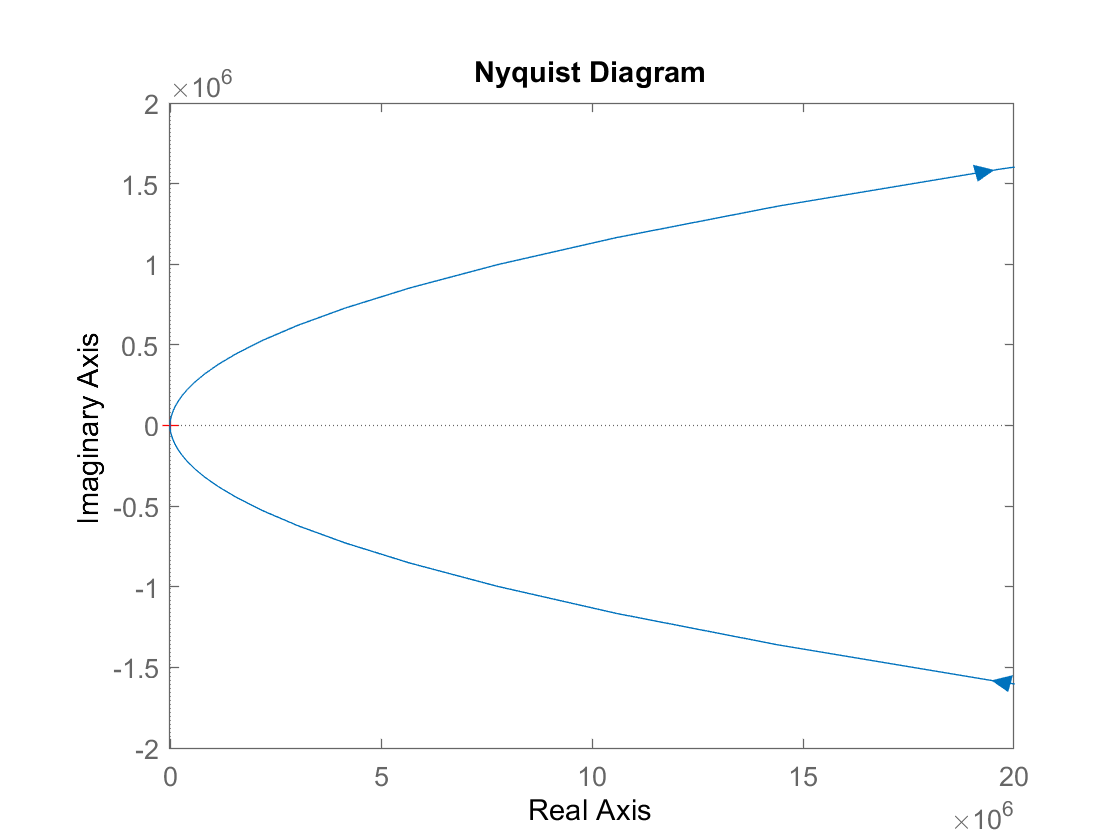


%subs(poly2sym(z{1,1},s_),s_,s_*i)

%clear w_;syms w_;assume(w_,'real');assume(w_ >= 0);
%clear s_;syms s_;

nyquist(F_det)

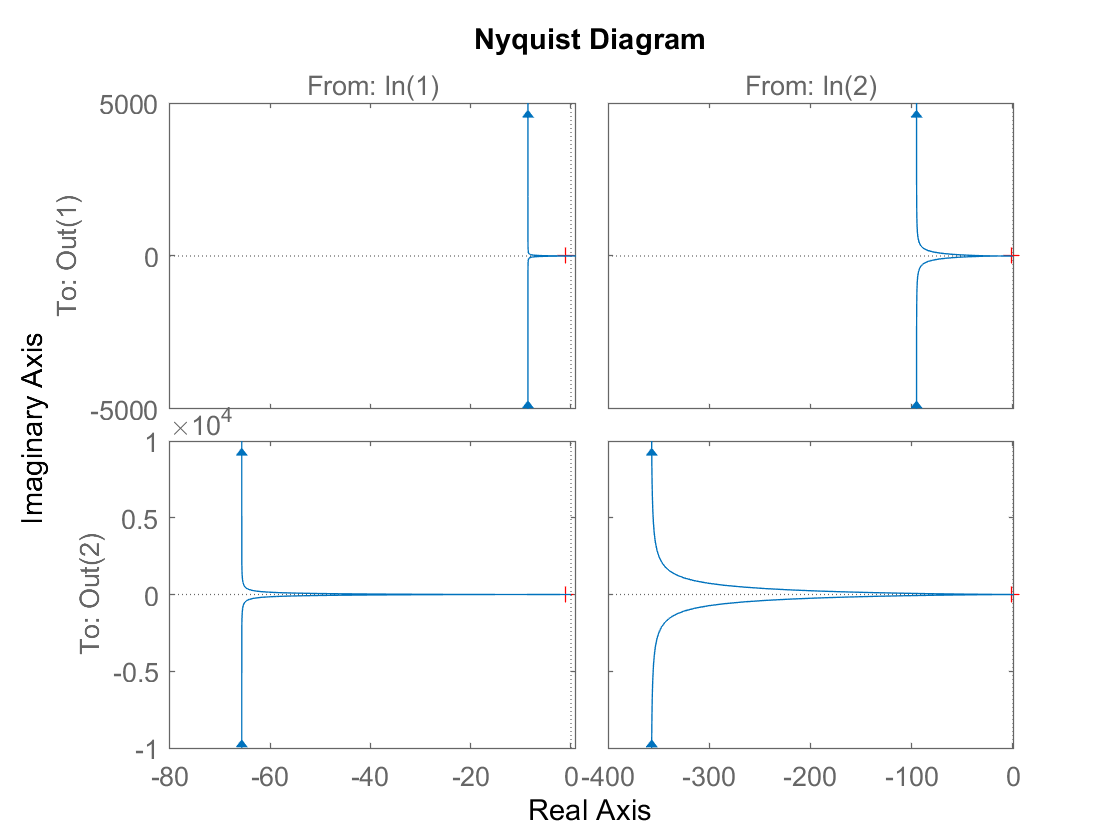

nyquist(F)

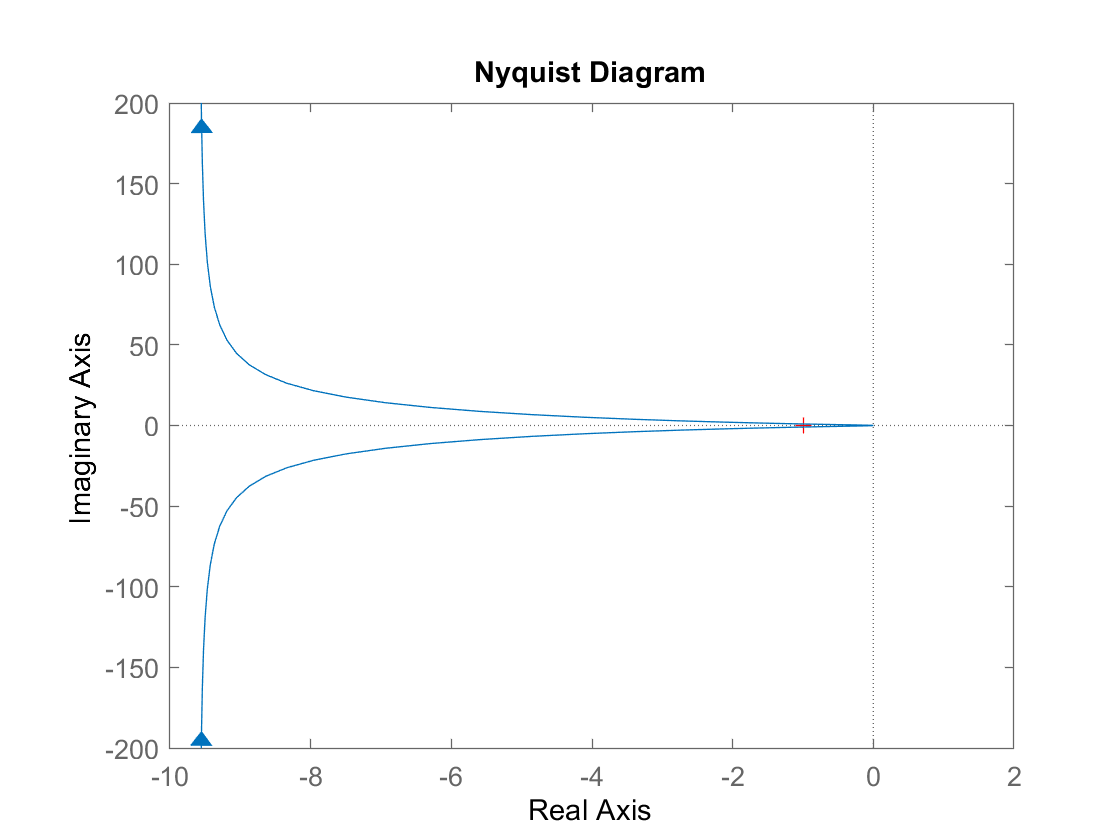

nyquist(G_ol(1,1))

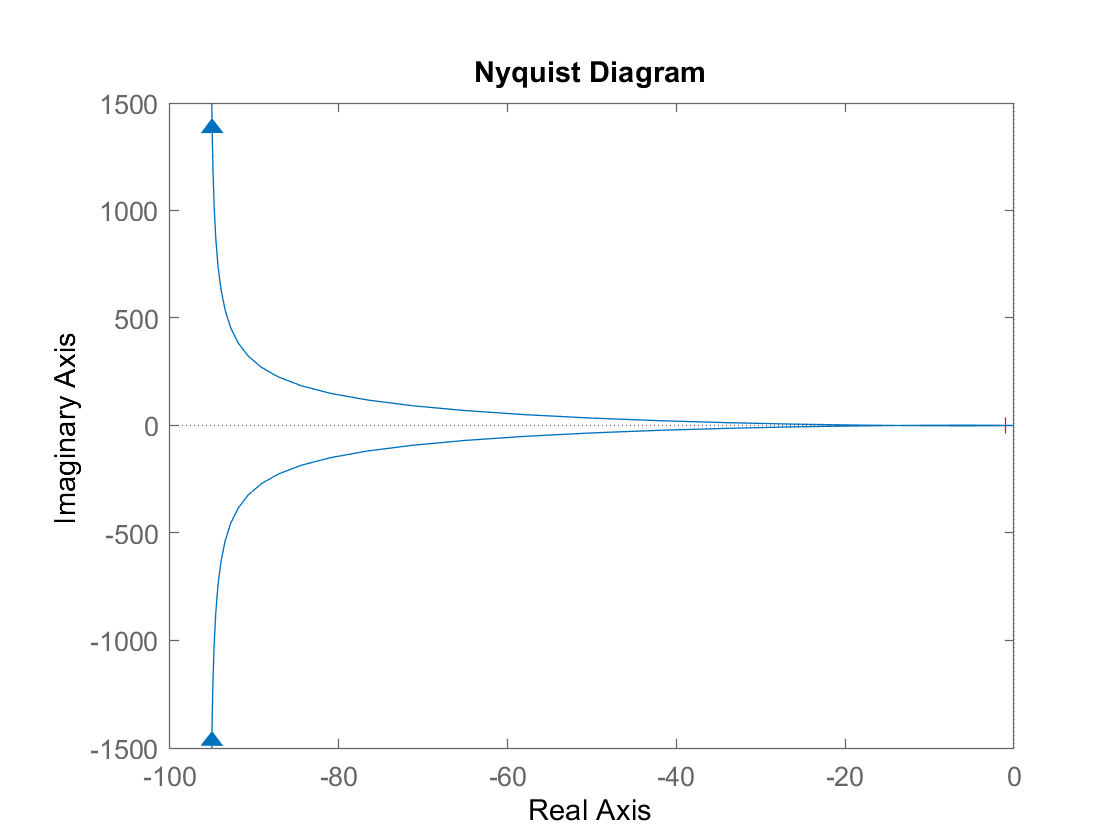

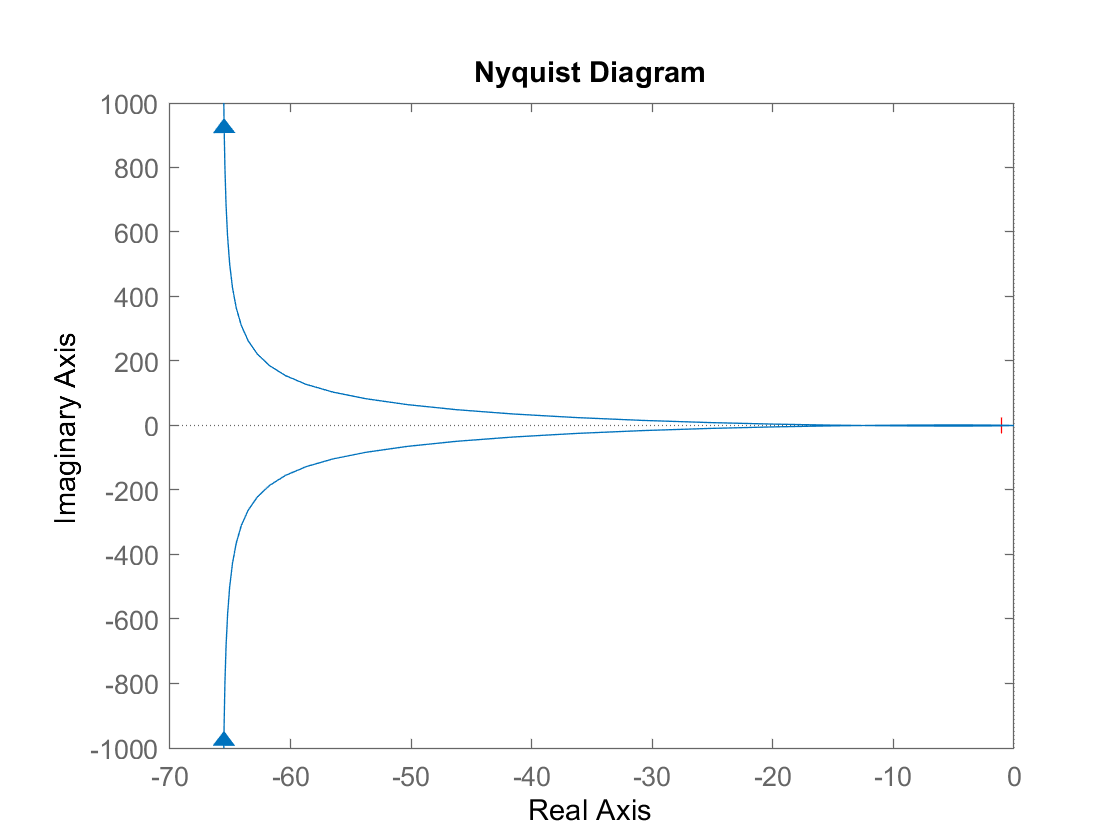

nyquist(G_ol(1,2))

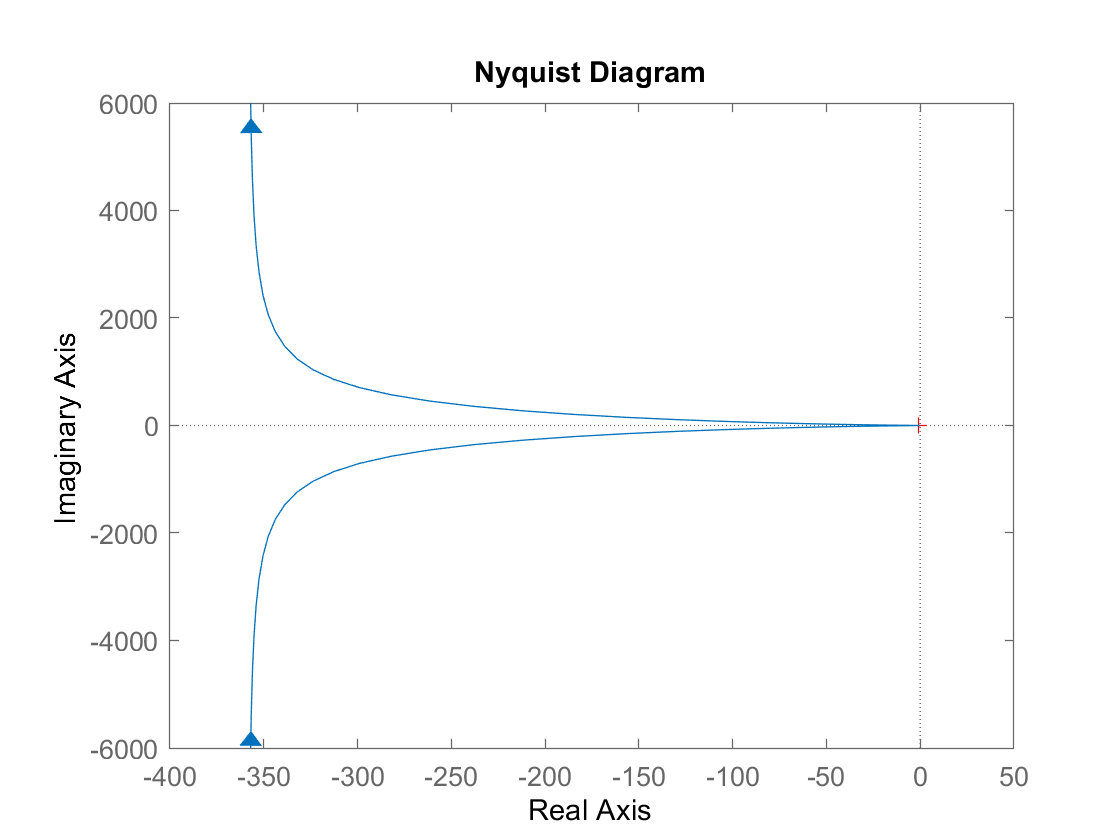

nyquist(G_ol(2,2))

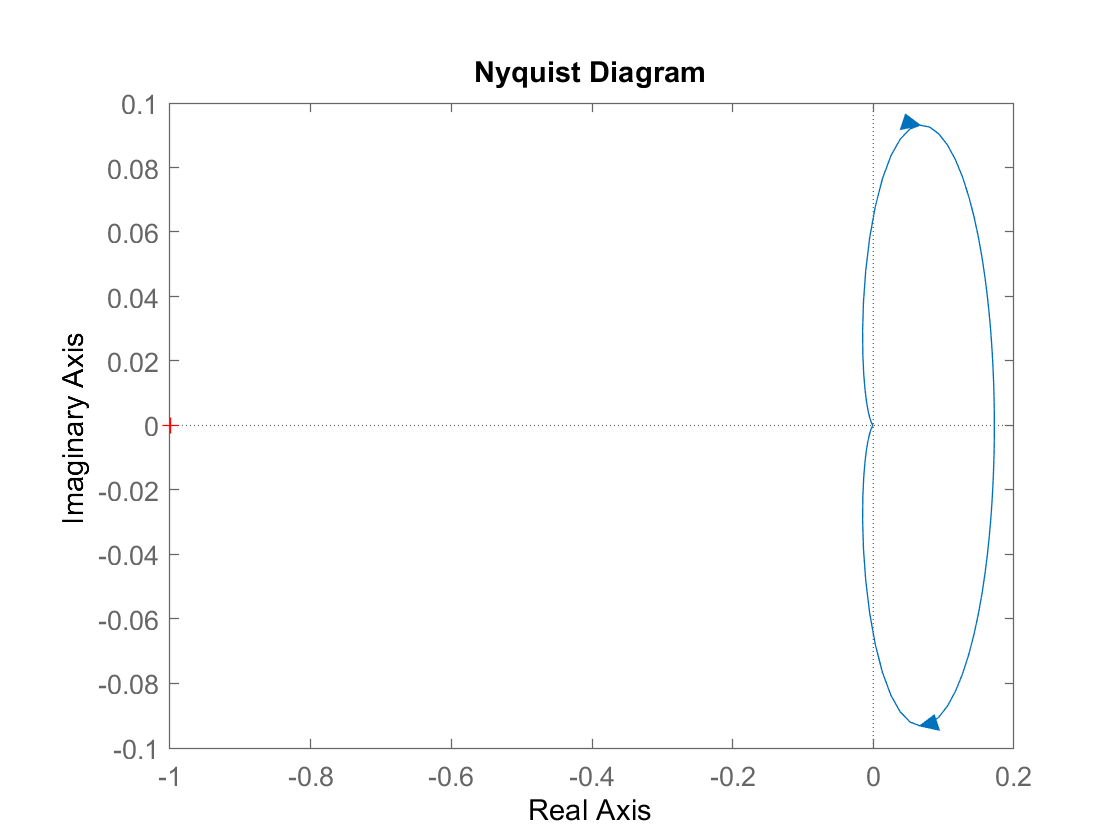

nyquist(Gw_det)

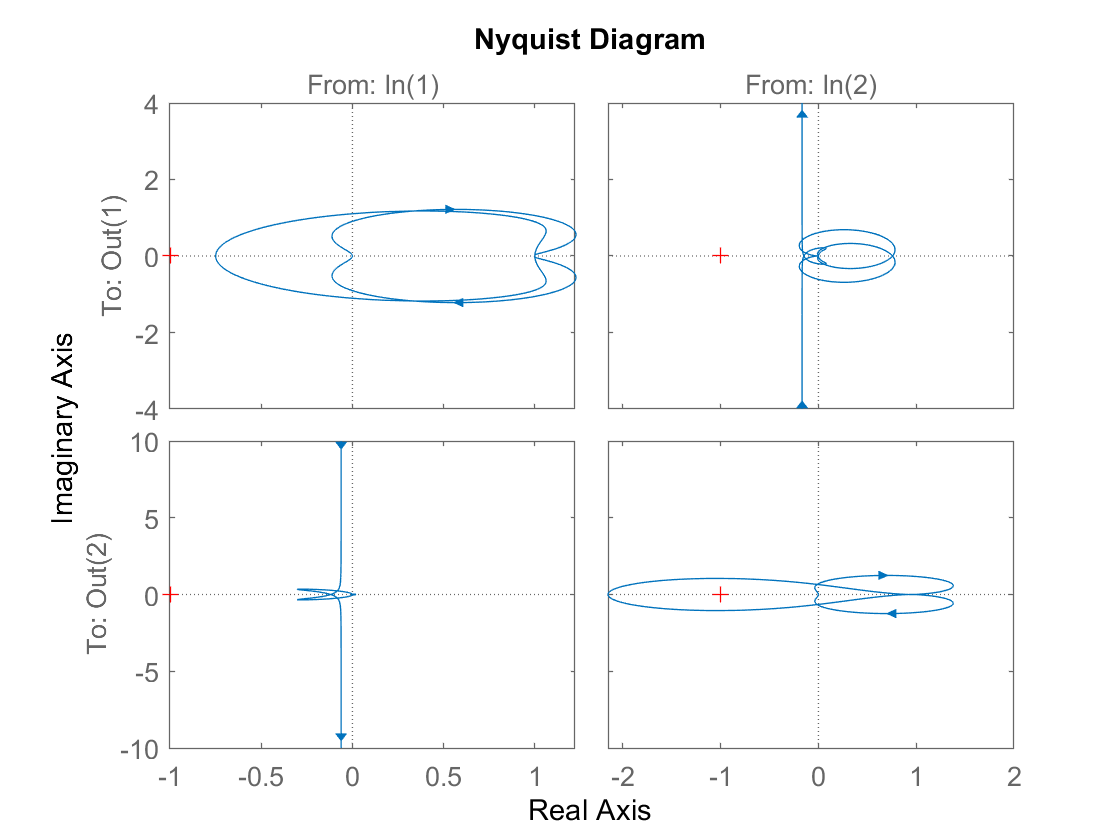

nyquist(Gw)

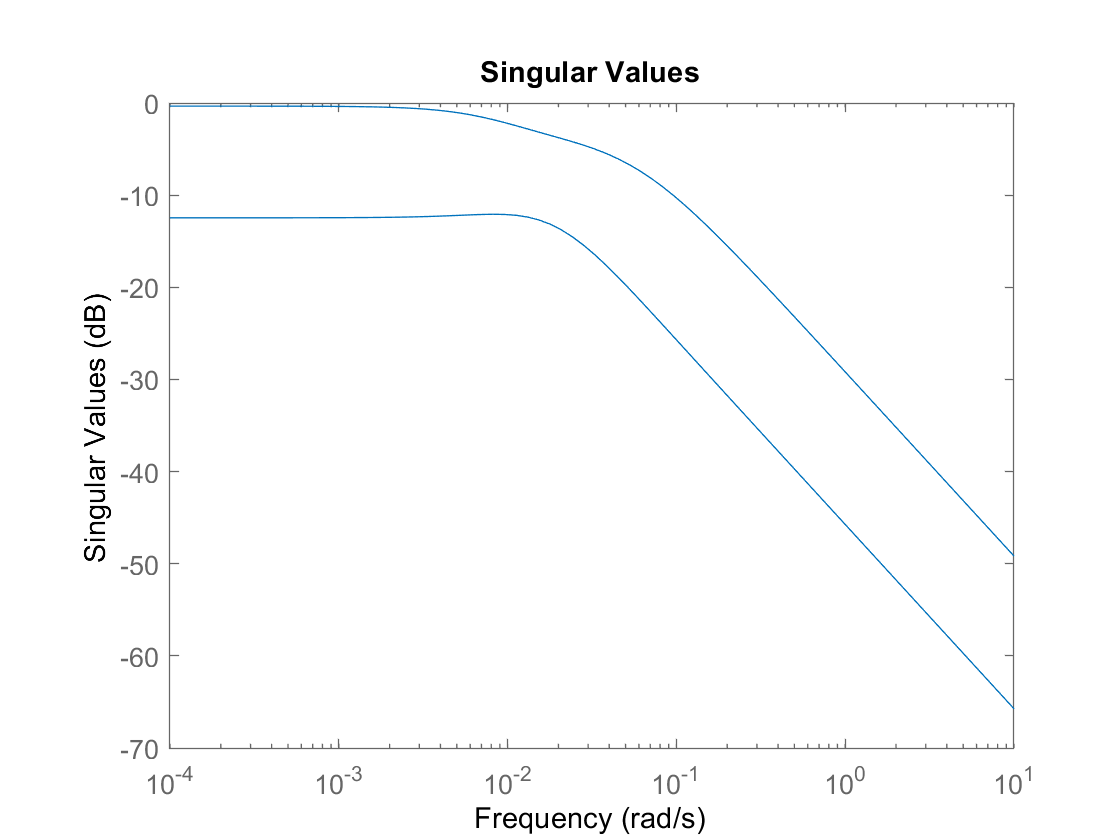

 
%% Sensitivität
%sigma calculates the singular values of the frequency response of a dynamic system sys.
figure(3); sigma(G);


%% Berechnung von  Sensitivitaeten - Compute Sensitivities 
% Nach Defninition
% According to definition
S = inv(eye(2) + G_ol);
T = S*G_ol;

%T_pi = feedback(G_ol, 1);
%step(T_pi)



function ret=n_search(G_)
    p_=real(pole(G_));
    n0=0;
    n_plus=0;
    for n=1:size_tf(G_)
        if p_(n,1)==0
            n0=n0+1;
        elseif p_(n,1) > 0
            n_plus=n_plus+1;
        end
    end
    ret=[n0;n_plus];
end

function ret=size_tf(G_)
    ret=size(tf2sym(G_),1);
end
function ret=RGA(Matrix_data)
    ret=Matrix_data.*((inv(Matrix_data)).');
end

function ret=RGA_Norm(Matrix_data) %wc ... Phasen durchtritsfrequenz also |Gol(s)|=1
    foo=RGA(Matrix_data)-eye(size(Matrix_data,1));
    ret=Matrix_norm_sum(foo);
end

function ret=PI_manuel(G,wc,phi)
    G_=tf2sym(G);
    G_=subs(G_,p,i*wc);
    syms Kp_ KI_;
    assume(Kp_ >= 0);assume(Kp_,'real');
    assume(KI_ >= 0);assume(KI_,'real');
    
    K_=KP_+KI_/(i*wc);
    H_=G*K;
    eq1_=sqrt(real(H_)^2+imag(H_)^2)==1;
    eq2_=atan2(imag(H_),real(H_));
end


%Matrix Norm Function
function ret=Matrix_norm_sum(Matrix_data)
    ret=0;
    [m,n]=size(Matrix_data);
    for mCnt=1:m
        for nCnt=1:n
            ret=ret+sqrt(Matrix_data(mCnt,nCnt)^2);
        end
    end
end

function ret=EW_get(A)
    clear lambda;
    syms lambda;
    eq_=det(lambda*eye(size(A,1))-A)==0;
    ret=solve(eq_,lambda);
    clear lambda;
end

function ret=RosenbrockMatrix_get(lambda,A,B,C,D)
 if ~exist('D','var')
     D=zeros(size(C,1),size(B,2));
 end
 ret=[(lambda*eye(size(A,1))-A) -B;C D];
end

function ret=INS_get(A,B,C)
    clear lambda;
    syms lambda;
    eq_=det(RosenbrockMatrix_get(lambda,A,B,C))==0;
    ret=simplify(solve(eq_,lambda));
end

%function ret=UNS()%ÜNS..ÜbertragungsNullstellen

%end

%Matlab symbolic to transferfunc. toolbox converter
function ret = sym2tf(g)
    [n,m]=size(g);
    for i=1:n
        for j=1:m
            [num,den]=numden(g(i,j));
            num_n=sym2poly(num);
            den_n=sym2poly(den);
            ret(i,j)=tf(num_n,den_n);
        end
    end
end

%Matlab symbolic to transferfunc. toolbox converter
function ret = tf2sym(G_)
p=sym('p');
[n,m]=size(G_);
ret=zeros(n,m);
ret=sym(ret);
for i=1:n
    for j=1:m
        [num,den]=tfdata(G_(i,j),'v');
        l=length(den);
        order=l;
        for k=1:l
            A(order,1)=p^(k-1);
            order=order-1;
        end
        n=num*A;
        d=den*A;
        ret(i,j)=n/d;
        clear A;
    end
end

ret=simplify(ret);
end

function ret = tf2sym2(G_tf,data)
    p=sym('p');
    Gsym=tf2sym(G_tf);
    ret=subs(Gsym,p,data);
end

function ret = tf2data(G_tf,data)
    p=sym('p');
    Gsym=tf2sym(G_tf);
    ret=subs(Gsym,p,data);
end

function ret=nyquistPlot_get_tf2(F_tf,data)
    p=sym('p');
    Fsym=tf2sym(F_tf);
    F_det_sym=det(Fsym);
    ret=subs(F_det_sym,p,data);
end

function ret = UNS_get_tf(G_tf)
    p=sym('p');
    Gsym=tf2sym(G_tf);
    eq_=det(G_tf)==0;
    ret=solve(eq_,p);
end

function ret = pole_zeros_get_tf(G_)
clear w_;syms w_;assume(w_,'real');assume(w_ >= 0);
clear s_;syms s_;

%ret.pole=zeros(2,2);
ret_data.pole(1,1)=pole(G_(1,1));
ret_data.pole(1,2)=pole(G_(1,2));
ret_data.pole(2,1)=pole(G_(2,1));
ret_data.pole(2,2)=pole(G_(2,2));
ret_data.UNS=UNS_get_tf(G_);
ret=ret_data;
end

function ret=abs_imag_polynom(p_)
    clear w_;syms w_;assume(w_,'real');%assume(w_ > 0);
    p_sym=tf2sym2(p_,i*w_);
    ret=sqrt(real(p_sym)^2+imag(p_sym)^2);
    %subs(poly2sym(z{1,1},s_),s_,s_*i)
end

function ret=zeilendominant(G_) 
    ret=1;
    clear w_;syms w_;assume(w_,'real');
    term1=simplify(abs_imag_polynom(G_(1,1)))*abs(w_);
    term1=vpa(subs(term1,w_,0));
    term2=simplify(abs_imag_polynom(G_(1,2)))*abs(w_);
    term2=vpa(subs(term2,w_,0));
    if(term1 <= term2)
        ret=0;
        return
    end
    term1=simplify(abs_imag_polynom(G_(2,2)))*abs(w_);
    term1=vpa(subs(term1,w_,0));
    term2=simplify(abs_imag_polynom(G_(2,1)))*abs(w_);
    term2=vpa(subs(term2,w_,0));
    if(term1 <= term2)
        ret=0;
        return
    end
end


function ret=spaltendominant(G_)
    ret=1;
    clear w_;syms w_;assume(w_,'real');
    term1=simplify(abs_imag_polynom(G_(1,1)))*abs(w_);
    term1=vpa(subs(term1,w_,0));
    term2=simplify(abs_imag_polynom(G_(2,1)))*abs(w_);
    term2=vpa(subs(term2,w_,0));
    if(term1 <= term2)
        ret=0;
        return
    end
    term1=simplify(abs_imag_polynom(G_(2,2)))*abs(w_);
    term1=vpa(subs(term1,w_,0));
    term2=simplify(abs_imag_polynom(G_(1,2)))*abs(w_);
    term2=vpa(subs(term2,w_,0));
    if(term1 <= term2)
        ret=0;
        return
    end
%     ret=1;
%     [m,n]=size(G_);
%     data=G_(1,1).*zeros(n,1);
%     comp_val=G_(1,1).*zeros(m,1);
%     for nCnt=1:n
%         for mCnt=1:m
%             if mCnt == nCnt
%                 comp_val(nCnt)=sqrt(G_(mCnt,nCnt)^2);
%             else
%                 data(nCnt)=data(nCnt)+G_(mCnt,nCnt)^2;
%             end
%         end
%         sqrt(data(nCnt))
%         if comp_val(nCnt) <= data(nCnt)
%             ret=0;
%             return;
%         end
%     end
end